# `Exercise 1)`

# `Task A)`

clear;
% given data
u=[1 2 3 4 5]';
y=[6 7 8 9 -1]';

% you can test the following calls. After the call the correct answer is
% given

uy2phi([y u],[1 1 0])

ans =      7     6     2
     8     7     3
     9     8     4
    -1     9     5


%      7     6     2
%      8     7     3
%      9     8     4
%     -1     9     5

uy2phi([y u],[1 1 1])

ans =      7     6     1
     8     7     2
     9     8     3
    -1     9     4


%      7     6     1
%      8     7     2
%      9     8     3
%     -1     9     4

uy2phi([y u],[1 1 2])

ans =      8     7     1
     9     8     2
    -1     9     3


%      8     7     1
%      9     8     2
%     -1     9     3

uy2phi([y u],[1 2 2])

ans =      9     8     2     1
    -1     9     3     2


%      9     8     2     1
%     -1     9     3     2

uy2phi([y u],[3 2 2])

ans =      9     8     7     6     2     1
    -1     9     8     7     3     2


%      9     8     7     6     2     1
%     -1     9     8     7     3     2

# `Task C)`

clear;
% given data
u=[1 -1 2 -1 3 0 1]';
y=[2 -2 -3 -4 -2 0 1]';

% Your estimate should be
model=arxfit([y u],[2 1 2]);

model.theta

ans =     1.1573
   -0.5004
    0.2366



%     1.1573
%    -0.5004
%     0.2366


idpredict(model,[y u],1)

ans =          0
    2.3146
   -3.0789
   -2.7077
   -2.6550
   -0.5496
    1.7105



%          0
%     2.3146
%    -3.0789
%    -2.7077
%    -2.6550
%    -0.5496
%     1.7105


idpredict(model,[y u],3)

ans =          0
         0
    0.2366
    0.8209
   -1.2256
   -0.2234
    0.5249



%          0
%          0
%     0.2366
%     0.8209
%    -1.2256
%    -0.2234
%     0.5249


ysim=idsimulate(model,u)

ysim =          0
         0
    0.2366
    0.0372
    0.3978
    0.2052
    0.7481



%          0
%          0
%     0.2366
%     0.0372
%     0.3978
%     0.2052
%     0.7481

# `Task D)`

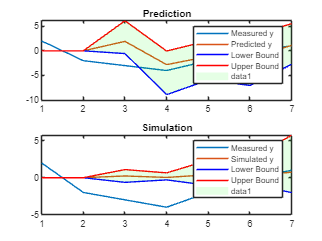

% The following two calls give the figures displayed in the project
% instructions

idcompare(model,[y u],2)

idcompare(model,[y u],Inf)

Error using horzcat
Dimensions of arrays being concatenated are not consistent.

Error in idpredict (line 13)
            phi = [[zeros(k,model.na); y_pred(k:end-1), phi(k:length(phi)-1,1:model.na-1)], [phi(:,model.na+1:end)]];

Error in 

# `Exercise 2) Funtions Validation`

clear;
%  multiple sets of true system parameters
B_true = [1, 1];
A_true = -[1, 0.1];

N = 10000;  % data points
noise_variance = 1;

nk = 0;  

% Generate input data
u = randn(N, 1);

% noise-free system output using the current true parameters
y_true = filter([B_true], [1, -A_true], u);

% white noise to the output
noise = sqrt(noise_variance) * randn(N, 1);
y_noisy = y_true + noise;

% Fit models
nb = length(B_true);  % Number of B coefficients
na = length(A_true);  % Number of F coefficients in OE model

arx_model = arxfit([y_noisy, u], [na, nb, nk]);
oe_model = oefit([y_noisy, u], [nb, na, nk]);

% Display results
%fprintf('\nParameter Set %d:\n', i);
disp('True B coefficients:');

True B coefficients:


disp(B_true);

     1     1



disp('Estimated B coefficients from OE model:');

Estimated B coefficients from OE model:


disp(oe_model.B);

    1.0090
    0.9130



disp('Estimated B coefficients from ARX model:');

Estimated B coefficients from ARX model:


disp(arx_model.B);

    1.0097
    0.0323



disp('True A coefficients:');

True A coefficients:


disp(A_true);

   -1.0000   -0.1000



disp('Estimated A coefficients from OE model:');

Estimated A coefficients from OE model:


disp(oe_model.F);

   -0.9056
   -0.1118



disp('Estimated A coefficients from ARX model:');

Estimated A coefficients from ARX model:


disp(arx_model.A);

   -0.0355
   -0.0300

